clf
clear all

format shortg




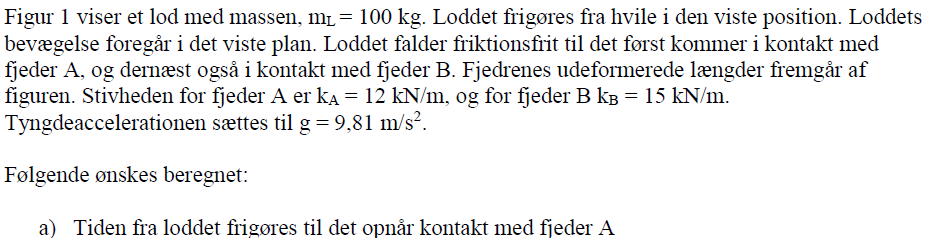

m_L = 100;
k_A = 12000; %N/m
k_B = 15000; %N/m

g = 9.81;


Loddet frigøres med hastigheden $v_0 = 0$ således får vi

y = 0.75; %m
syms t
eq = y == g * t^2 /2

$$eq = \frac{3}{4}=\frac{981\,t^{2}}{200}$$


t_sol = solve(eq, t);
t_A = t_sol(2);
vpa(t_A, 4)

$$ans = 0.391$$

Tiden til loddet rammer fjeder A er således $0,391\ s$

b)Loddets hastighed ved kontakt med fjeder A

v = g * t_A;
vpa(v)

$$ans = 3.8360135557633265485707248211545$$

Hastigheden er ved kontakt med fjederen $3,84\ m/s$

c) Loddets kinetiske energi, når loddet opnår kontakt med fjeder A

T = 1/2 * m_L * v^2;
vpa(T)

$$ans = 735.75$$

Den kinetiske energi af lodet ved A er $735,75\ J$

d) Loddets bevægelsesmængde (linear momentum) når loddet opnår kontakt med fjeder A

G = v * m_L;
vpa(G)

$$ans = 383.60135557633265485707248211545$$

Loddets bevægelsesmængde er således $383,6\ kg * m / s$

e) Den maksimale sammentrykning af fjeder A, når loddet igen kommer i hvile

Impulsbevarelse:

% x = 0.1
syms x
G_lod = m_L * g * (x + 0.75)

$$G\_lod = 981\,x+\frac{2943}{4}$$

K_A = k_A * (x)^2 / 2 

$$K\_A = 6000\,x^{2}$$

K_B = k_B * (x-0.1)^2 / 2  

$$K\_B = 7500\,{\left(x-\frac{1}{10}\right)}^{2}$$


eq = G_lod == K_A + K_B % her kan ikke bruges kinetisk energi da vi ikke kender hastigheden efter A

$$eq = 981\,x+\frac{2943}{4}=7500\,{\left(x-\frac{1}{10}\right)}^{2}+6000\,x^{2}$$


x_tryk = solve(eq, x)

$$x\_tryk = \left(\begin{array}{c} \frac{827}{9000}-\frac{\sqrt{4648429}}{9000}\\ \frac{\sqrt{4648429}}{9000}+\frac{827}{9000} \end{array}\right)$$

vpa(x_tryk(2),4)

$$ans = 0.3314$$

% G = -F * 


Således trykkes fjederene 0,33 m ned fra A

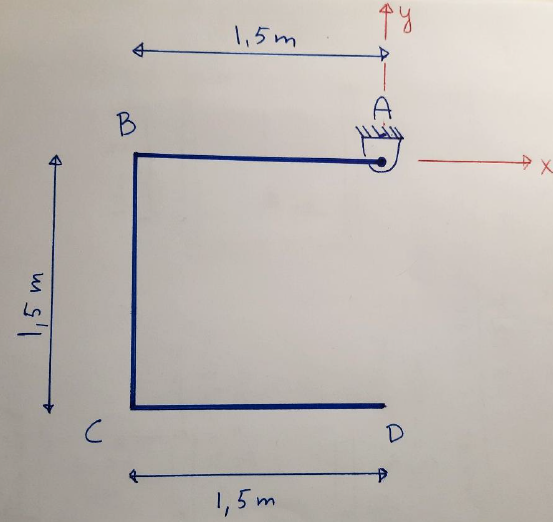

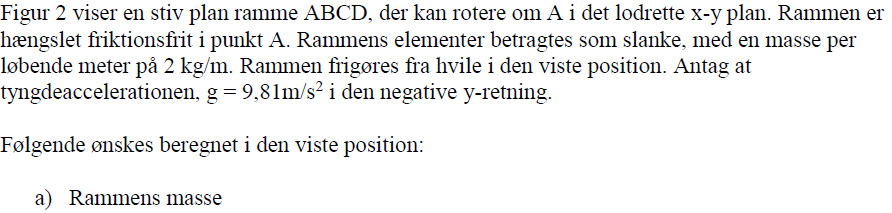

clear all

L = 1.5; %m
m_bar = 2; % kg/m
g = 9.81; %m/s^2

M_tot = 3*L * m_bar

M_tot =      9


b) Tyngdepunktets position, samt en skitse som illustrerer tyngdepunktets placering

% x_AB = -0.75
% y_AB = 0
% 
% x_BC = -1.5
% y_BC = -0.75
% 
% x_CD = -0.75
% y_CD = -1.5
% 
% G_x = (x_AB + x_BC + x_CD)/3
% G_y = (y_AB + y_BC + y_CD)/3


fra x-aksen

M = m_bar * L

M =      3


M_tot = 3 * M

M_tot =      9


Sx_AB = 0 * M

Sx_AB =      0


Sx_BC = -L/2 * M

Sx_BC =         -2.25


Sx_CD = -L * M

Sx_CD =          -4.5



y_G = (Sx_AB + Sx_BC + Sx_CD) / M_tot

y_G =         -0.75


fra y-aksen

Sy_AB = -L/2 * M

Sy_AB =         -2.25


Sy_BC = -L * M

Sy_BC =          -4.5


Sy_CD = -L/2 * M

Sy_CD =         -2.25



x_G = (Sy_AB + Sy_BC + Sy_CD) / M_tot

x_G =     -1


c) Masseinertimomentet om A

d_BC = L %forskydelsen af BC's tyngde punkt 

d_BC =           1.5



d_CD = L %forskydelsen af CD's tyngde punkt

d_CD =           1.5



stangAB_I_zz = 1/3 * M * L^2 %ligger op af rotations aksen

stangAB_I_zz =          2.25



stangBC_I_zz = 1/3 * M * L^2 + M*d_BC^2 % forskydes til rotations aksen

stangBC_I_zz =      9



stangCD_I_zz = 1/3 * M * L^2 + M*d_CD^2 % forskydes til rotations aksen

stangCD_I_zz =      9



disp('-----------------------------------------')

-----------------------------------------



%total inertimomentet er således
I_tot_zz = stangAB_I_zz + stangBC_I_zz + stangCD_I_zz

I_tot_zz =         20.25


e) Vinkelaccelerationen

% r = sqrt(x_G^2 + y_G^2)
r = abs(x_G) % armen til momentet

r =      1


M = M_tot * g * r

M =         88.29


% tau_eq = F * g == I_tot_zz * alpha;

alpha = M / I_tot_zz

alpha =          4.36


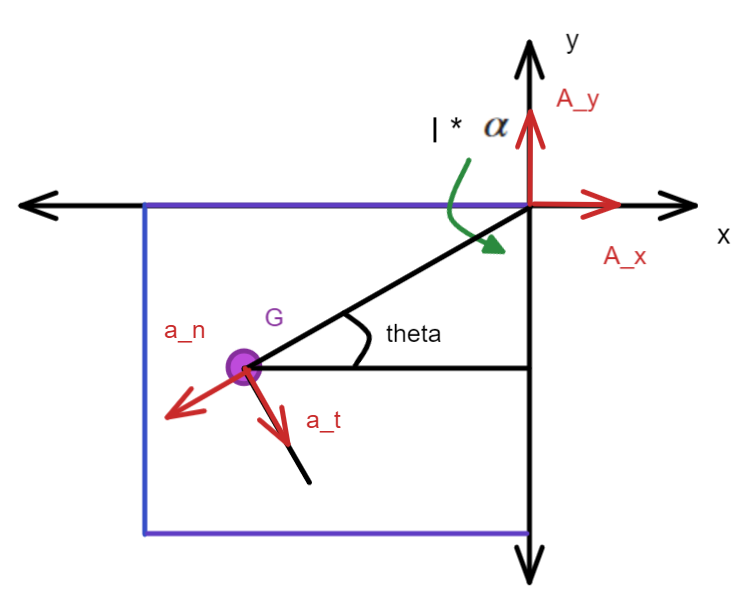

f) Tyngdepunktets acceleration i x- og y-retningerne, samt en skitse som illustrerer de to accelerationer

d = sqrt(x_G^2 + y_G^2)

d =          1.25


a_t = d * alpha 

a_t =          5.45



% a_x = d * omega^2

theta = atand(y_G/x_G)

theta =         36.87


% theta = 0
a_y = a_t * cosd(theta)

a_y =          4.36


a_x = -a_t * sind(theta)

a_x =         -3.27


g) Reaktionerne Ax og Ay

Ax = -a_x * M_tot 

Ax =         29.43


Ay = -(a_y * M_tot - M_tot*g) % tyngdekraften trækkes fra da denne går ned af og reaktionen trækker op.

Ay =         49.05


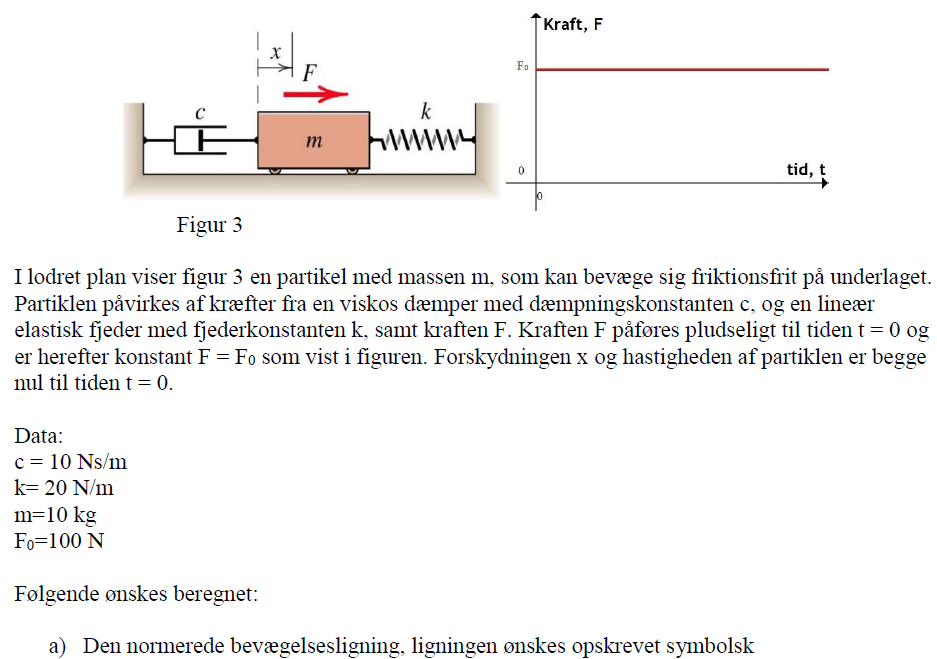


$$F = m*a \\
a = \ddot{x} = F/m$$



$$\sum F_x = m\cdot\ddot x
\\
F_0 -c \dot x - kx = m\ddot x
\\
\ddot x + \frac{c}{m}\dot x + \frac{k}{m}x = \frac{F_0}{m} 
\\
\ddot x + 2\zeta\omega_n\dot x + \omega_n^2x = \frac{F_0}{m}$$


c = 10

c =     10


k = 20

k =     20


m = 10

m =     10


F_0 = 100

F_0 =    100


b) Egenfrekvensen ωn

w_n = sqrt(k/m) %egensvingningen

w_n =        1.4142


c) Dæmpningsforholdet ζ og afgør typen af dæmpning (overdæmpet, kritisk dæmpet eller underdæmpet)

zeta = c/(2 * m * w_n) % viscous damping factor or damping ratio

zeta =       0.35355


d) Den dæmpede egenfrekvens ωd

w_d = w_n*sqrt(1-zeta^2) % damped natrual freqancy

w_d =        1.3229


e) Vis at xp(t) = F0/k er en partikulær løsning til bevægelsesligningen


$$\ddot x + 2\zeta\omega_n\dot x + \omega_n^2x = \frac{F_0}{m}$$



$$x(t) = \frac{F_0}{k} \\
x'(t) = 0 \\
x''(t) = 0$$


vi får nu


$$\omega_n^2 \frac{F_0}{k} = \frac{F_0}{m} \\
\omega_n^2 = \frac{k}{m} \\
\frac{F_0}{m} = \frac{F_0}{m} $$


f) Forskydningen x(t)

(Hint: anvend ligning (8/11) i lærebogen for bestemmelse af den fuldstændige løsning til den homogene bevægelsesligning)

syms f(t) t f_1(t) A_3 A_4
t0 = 0

t0 =      0


disp('Værdierne ved t = 0 findes for sted og hastighedsfunktionen')

Værdierne ved t = 0 findes for sted og hastighedsfunktionen


x_0 = 0 % m %start stedet

x_0 =      0


V_0 = 0 % m/s %start hastigheden

V_0 =      0



x_p = (F_0/k)

x_p =      5


f(t) = x_p + (A_3 * cos(w_d * t) + A_4 * sin(w_d * t) )* exp(-zeta * w_n * t)

$$f(t) = {\mathrm{e}}^{-\frac{t}{2}}\,\left(A_{3}\,\cos\left(\frac{\sqrt{7}\,t}{2}\right)+A_{4}\,\sin\left(\frac{\sqrt{7}\,t}{2}\right)\right)+5$$


f_1(t) = diff(f(t), t) %% Hastigheds funktionen

$$f\_1(t) = {\mathrm{e}}^{-\frac{t}{2}}\,\left(\frac{\sqrt{7}\,A_{4}\,\cos\left(\frac{\sqrt{7}\,t}{2}\right)}{2}-\frac{\sqrt{7}\,A_{3}\,\sin\left(\frac{\sqrt{7}\,t}{2}\right)}{2}\right)-\frac{{\mathrm{e}}^{-\frac{t}{2}}\,\left(A_{3}\,\cos\left(\frac{\sqrt{7}\,t}{2}\right)+A_{4}\,\sin\left(\frac{\sqrt{7}\,t}{2}\right)\right)}{2}$$


[A_3_num, A_4_num] = solve([f(t0) == x_0, f_1(t0) == V_0], [A_3, A_4]);
A_3_ = vpa(A_3_num, 4)

$$A\_3\_ = -5.0$$

A_4_ = vpa(A_4_num, 4)

$$A\_4\_ = -1.89$$

g) Plot forskydningen x(t) for 0 ≤ t ≤ 10 s. I samme plot ønskes den statiske forskydning F0/k indtegnet


ts = linspace(0, 10, 100);
f(t) = subs(f(t), [A_3, A_4], [A_3_num, A_4_num])

$$f(t) = 5-{\mathrm{e}}^{-\frac{t}{2}}\,\left(5\,\cos\left(\frac{\sqrt{7}\,t}{2}\right)+\frac{5\,\sqrt{7}\,\sin\left(\frac{\sqrt{7}\,t}{2}\right)}{7}\right)$$

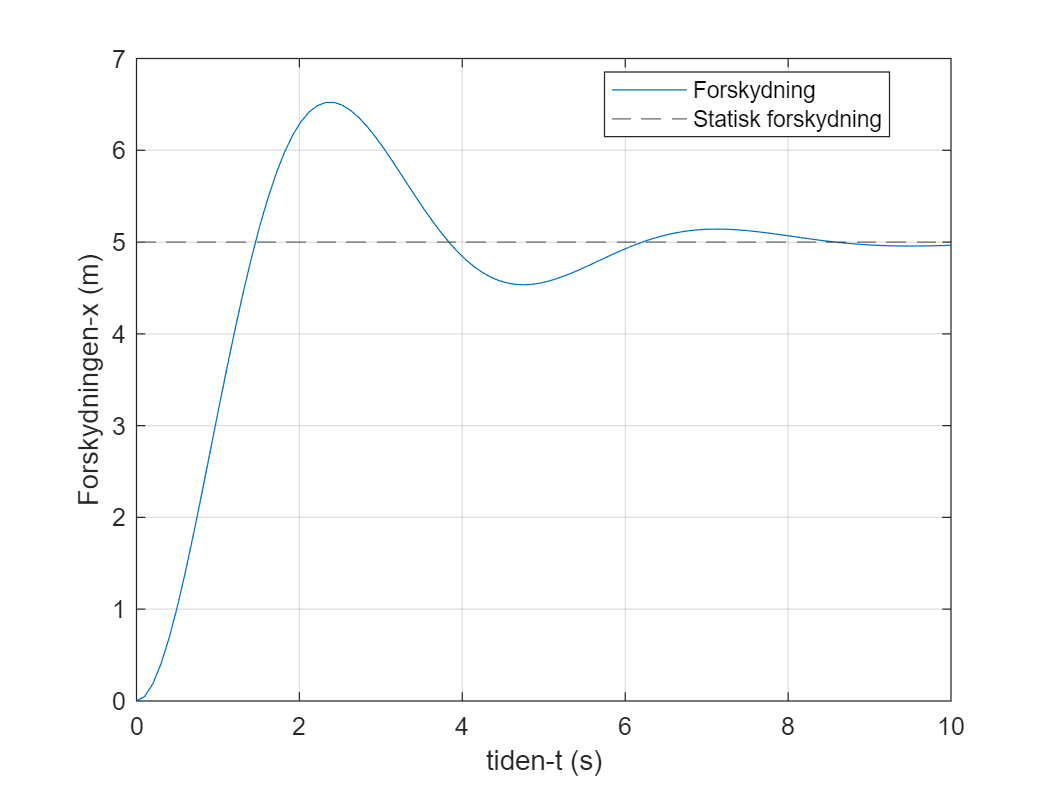

plot(ts, f(ts), 'DisplayName', 'Forskydning')
yline(F_0/k, '--', 'DisplayName', 'Statisk forskydning')
ylabel('Forskydningen-x (m)')
xlabel('tiden-t (s)')
grid('on')
legend('Location','best')

anden måde

clear
% Opgave data
c = 10;
k = 20;
m = 10;
F0 = 100;
t0 = 0; t1 = 10;

syms x1
x0 = F0/k; % N/(N/m) = m
% Formler

wn1 = sqrt(k/m);
zeta1 = c/(2*m*wn1);
wd1 = wn1*sqrt(1 - zeta1^2);

% Diff ligning
syms x(t) zeta lambda t A wn k m C wd psi x

x_plac = C*exp(-zeta*wn*t) * sin(wd*t + psi)  == x0;
% Til t0
x_plac_numt0 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t0]),3);
% til t1;
%x_plac_numt1 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t1]),3);

x_vel = diff(x_plac, t) == 0;
% til t0;
x_vel_numt0 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t0]),3);
% til t1;
%x_vel_numt1 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t1]),3);


eqst0 = [x_vel_numt0, x_plac_numt0];
%eqst1 = [x_vel_numt1, x_plac_numt1];
unks = [C, psi];

solt0 = solve(eqst0, unks);

psi = solt0.psi % Den største absolutte værdi skal vælges for psi og C

$$psi = \left(\begin{array}{c} 1.2094292028846515477720268022864\\ -1.9321634507051416906906165809931 \end{array}\right)$$

C = solt0.C   %

$$C = \left(\begin{array}{c} 5.3452248382556340499300035741502\\ -5.3452248382556340499300035741502 \end{array}\right)$$

 
C = vpa(solt0.C(1),4)

$$C = 5.345$$

psi = vpa(solt0.psi(2),4)

$$psi = -1.932$$


x_plac = vpa(C*exp(-zeta1*wn1*t1) * sin(wd1*t1 + psi),3)

$$x\_plac = -0.0344$$

g)

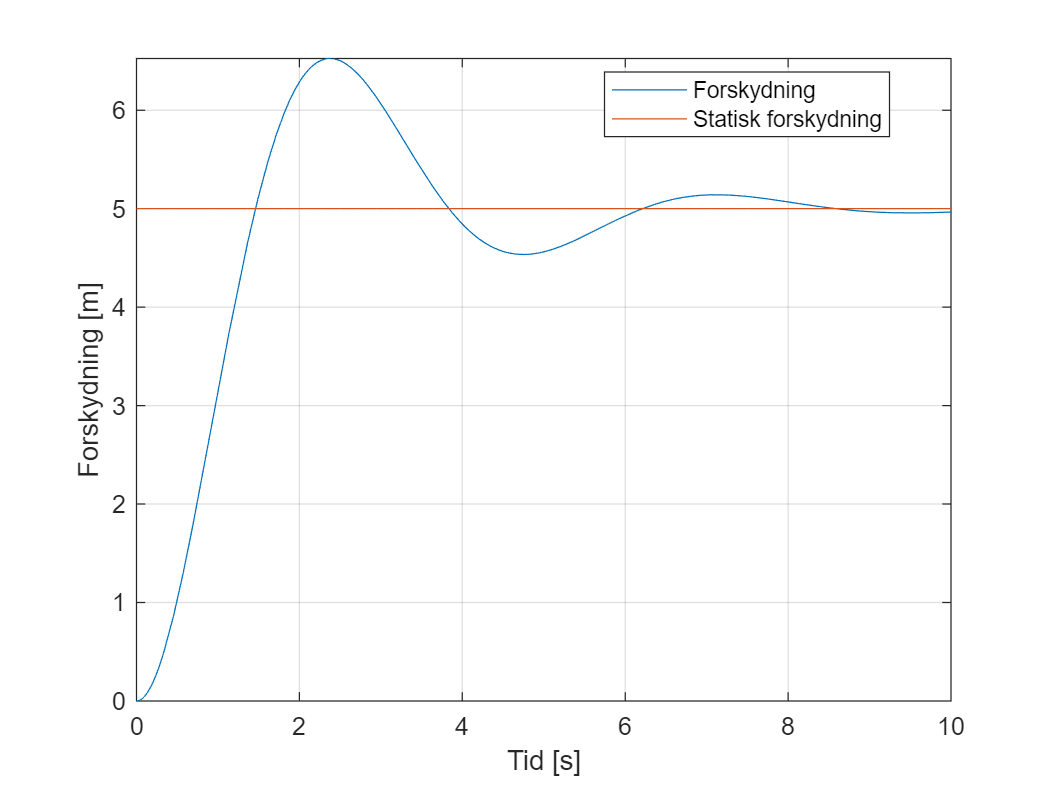

syms func(t)
xp = x0;

func(t) = C*exp(-zeta1*wn1*t) * sin(wd1*t + psi) + xp;

fplot(func(t), [0,10], "DisplayName", "Forskydning"), xlabel("Tid [s]"), ylabel("Forskydning [m]")
hold on
fplot(xp, [0,10], "DisplayName", "Statisk forskydning"), grid()
legend("Location", "best")
hold off

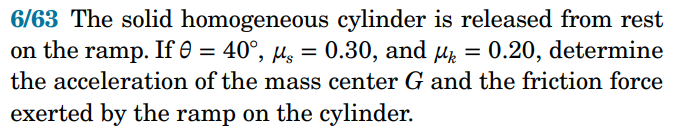

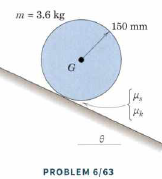

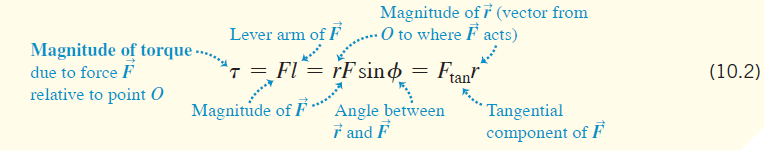

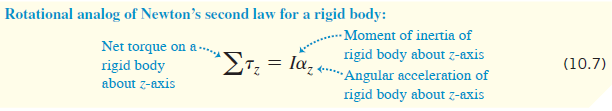

g = 9.81

g =          9.81


mu_s = 0.30

mu_s =           0.3


mu_k = 0.20

mu_k =           0.2


theta = 40

theta =     40


m = 3.6

m =           3.6


r = 0.15

r =          0.15



F_gx = m * g *  sind(theta) %tyngdegraft i x-retningen

F_gx =        22.701


F_gy = m * g *  cosd(theta) %tyngdegraft i y-retningen

F_gy =        27.054


I = m * r^2 / 2

I =        0.0405


Vi opstiller 2 ligninger med to ubekendte for at finde tangial kraften af cylinderen F og accelerationen a

syms F a
eq_x = - F + F_gx == m * a

$$eq\_x = \frac{6389675407603979}{281474976710656}-F=\frac{18\,a}{5}$$


alpha = a / r % glider ikke

$$alpha = \frac{20\,a}{3}$$

eq_M = F * r == I * alpha

$$eq\_M = \frac{3\,F}{20}=\frac{27\,a}{100}$$


[F, a] = solve([eq_M, eq_x], [F, a]);
F = vpa(F, 4)

$$F = 7.567$$

a = vpa(a, 4)

$$a = 4.204$$

Tester om ren rulninger er overhold ved at se om $F_s > F$

N = F_gy

N =        27.054


F_s = mu_s * N %friktions kraften

F_s =        8.1161


Dette er overholdt og der er rulning